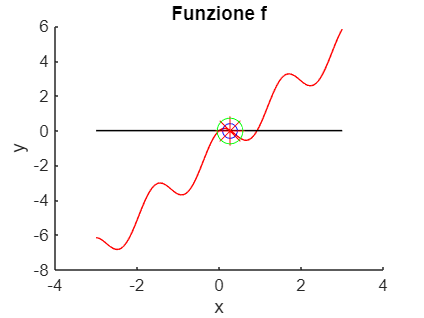

close all
clear
clc

f = @(x) cos(4 .* x) + 2 .* x - 1; % Così, con @(x) sto dicendo qual è il parametro in input e f diventa un puntatore alla funzione
fd = @(x) - 4 .* sin(4 .* x) + 2;

x = linspace(-3, 3, 200); % Prende in input x1, x2, n e crea n punti equidistanziati tra x1 e x2
y = f(x);


figure;
hold on;
plot(x, y, "-r");
plot(x, zeros(size(x)), "-k");
title("Funzione f");
xlabel("x");
ylabel("y");

[xb, kb] = bisec(f, 0, 0.5, 1e-10, 1000);

[xn, kn] = newton(f, fd, 0.5, 1e-10, 100);

[xc, kc] = corde(f, fd(0.5), 0.5, 1e-10, 100);

[xs, ks] = secanti(f, 0.1, 0.5, 1e-10, 1000);

plot(xb, f(xb), "Ob", "DisplayName", "Radice bisec", "MarkerSize", 8);

plot(xn, f(xn), "Xk", "DisplayName", "Radice Newton", "MarkerSize", 12);

plot(xc, f(xc), "*r", "DisplayName", "Radice corde", "MarkerSize", 16);

plot(xs, f(xs), "og", "DisplayName", "Radice secanti", "MarkerSize", 14);

hold off;